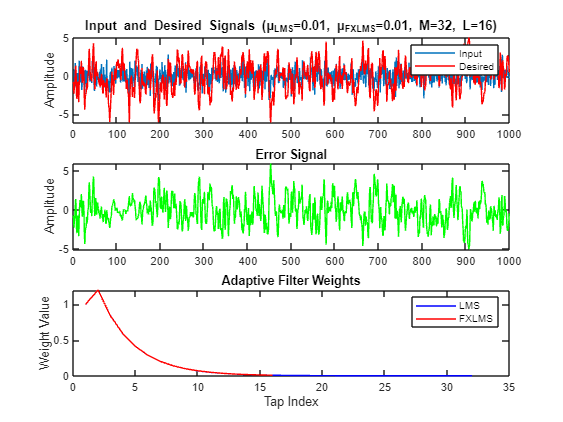

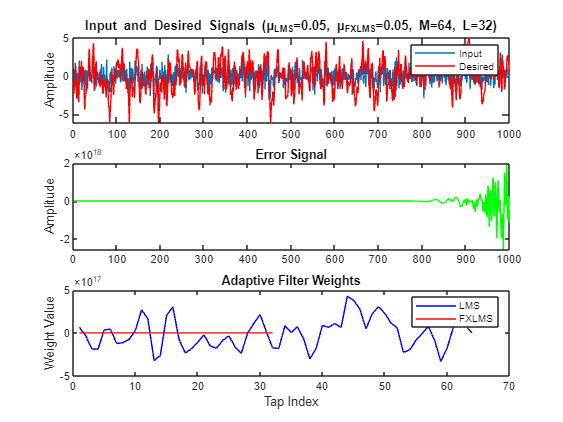

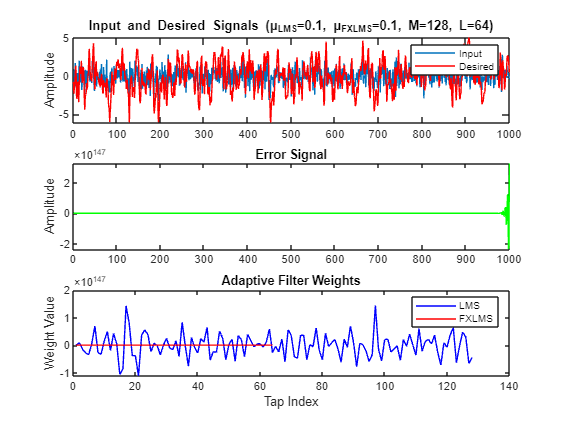

clear all; 
close all; 
clc;

% Parameters for the significant points
significant_points = [
    struct('mu_lms', 0.01, 'mu_fxlms', 0.01, 'M', 32, 'L', 16),   % Low μ for both LMS and FXLMS, Low M and L
    struct('mu_lms', 0.05, 'mu_fxlms', 0.05, 'M', 64, 'L', 32),   % Medium μ for both LMS and FXLMS, Medium M and L
    struct('mu_lms', 0.1, 'mu_fxlms', 0.1, 'M', 128, 'L', 64)     % High μ for both LMS and FXLMS, High M and L
];

% Initialize variables to store results
results = cell(size(significant_points));

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Loop over the significant points
for k = 1:numel(significant_points)
    mu_lms = significant_points(k).mu_lms;
    mu_fxlms = significant_points(k).mu_fxlms;
    M = significant_points(k).M;
    L = significant_points(k).L;
    
    % Initialize weight vectors
    w_lms = zeros(M,1);     % Filter weights for LMS primary path
    w_ref = zeros(L,1);     % Filter weights for FXLMS reference path

    % Buffers
    x_buf_lms = zeros(M,1);
    y_buf = zeros(length(d),1);
    x_buf_fxlms = zeros(L,1);

    % Main loop
    for n = (max(M,L)+1):length(x)

        % LMS
        % Shift input buffer for LMS
        x_buf_lms = x(n:-1:n-M+1); 

        % FIR filter output for LMS primary path
        y_lms = w_lms'*x_buf_lms;

        % Error signal for LMS
        e_lms = d(n) - y_lms;

        % Update weight vector for LMS
        w_lms = w_lms + mu_lms * e_lms * x_buf_lms;

        % FXLMS
        % Shift input buffer for FXLMS reference path
        x_buf_fxlms = x(n:-1:n-L+1);

        % FIR filter output for FXLMS reference path
        y_ref = w_ref'*x_buf_fxlms;

        % Error signal for FXLMS
        e_fxlms = d(n) - y_ref;

        % Update weight vector for FXLMS
        w_ref = w_ref + mu_fxlms * e_fxlms * x_buf_fxlms;

        % Final estimate combining both LMS and FXLMS
        y = y_lms + y_ref;
        y_buf(n) = y;
    end

    % Store results
    results{k} = struct(...
        'mu_lms', mu_lms, ...
        'mu_fxlms', mu_fxlms, ...
        'M', M, ...
        'L', L, ...
        'x', x, ...
        'd', d, ...
        'y_buf', y_buf, ...
        'w_lms', w_lms, ...
        'w_ref', w_ref ...
    );
end

% Plot signals and weights for each significant point
for k = 1:numel(significant_points)
    figure;
    subplot(3,1,1);
    plot(results{k}.x); hold on; plot(results{k}.d,'r'); legend('Input','Desired');
    ylabel('Amplitude');
    title(['Input and Desired Signals (μ_{LMS}=' num2str(results{k}.mu_lms) ', μ_{FXLMS}=' num2str(results{k}.mu_fxlms) ', M=' num2str(results{k}.M) ', L=' num2str(results{k}.L) ')']);

    subplot(3,1,2);
    plot(results{k}.d-results{k}.y_buf,'g'); 
    ylabel('Amplitude');
    title('Error Signal');

    subplot(3,1,3);
    plot(results{k}.w_lms, 'b'); hold on; plot(results{k}.w_ref, 'r');
    ylabel('Weight Value');
    xlabel('Tap Index');
    legend('LMS', 'FXLMS');
    title('Adaptive Filter Weights');
end

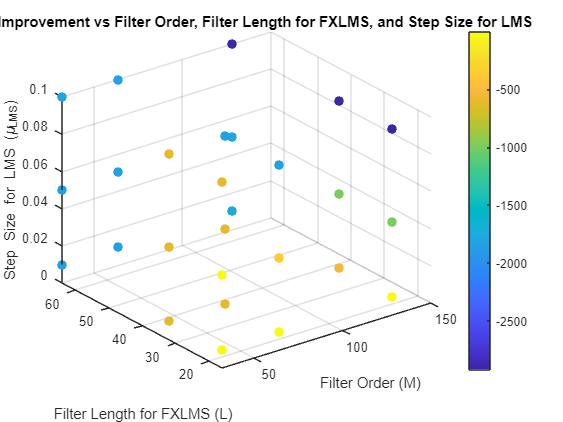


% Parameters for the significant points
significant_M_values = [32, 64, 128];  % Filter length (M)
significant_L_values = [16, 32, 64];   % Filter length for FXLMS (L)
significant_mu_lms_values = [0.01, 0.05, 0.1];  % Step size for LMS (μ_{LMS})
significant_mu_fxlms_values = [0.01, 0.05, 0.1];  % Step size for FXLMS (μ_{FXLMS})

% Initialize variables to store results
SNR_improvements = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values));
M_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values));
L_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values));
mu_lms_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values));
mu_fxlms_values = zeros(numel(significant_M_values), numel(significant_L_values), numel(significant_mu_lms_values), numel(significant_mu_fxlms_values));

% Loop over the significant points
for i = 1:numel(significant_M_values)
    M = significant_M_values(i);
    
    for j = 1:numel(significant_L_values)
        L = significant_L_values(j);
        
        for k = 1:numel(significant_mu_lms_values)
            mu_lms = significant_mu_lms_values(k);
            
            for l = 1:numel(significant_mu_fxlms_values)
                mu_fxlms = significant_mu_fxlms_values(l);
                
                % Initialize weight vectors
                w_lms = zeros(M,1);     % Filter weights for LMS primary path
                w_ref = zeros(L,1);     % Filter weights for FXLMS reference path

                % Buffers
                x_buf_lms = zeros(M,1);
                y_buf = zeros(length(d),1);
                x_buf_fxlms = zeros(L,1);

                % Main loop
                for n = (max(M,L)+1):length(x)

                    % LMS
                    % Shift input buffer for LMS
                    x_buf_lms = x(n:-1:n-M+1); 

                    % FIR filter output for LMS primary path
                    y_lms = w_lms'*x_buf_lms;

                    % Error signal for LMS
                    e_lms = d(n) - y_lms;

                    % Update weight vector for LMS
                    w_lms = w_lms + mu_lms * e_lms * x_buf_lms;

                    % FXLMS
                    % Shift input buffer for FXLMS reference path
                    x_buf_fxlms = x(n:-1:n-L+1);

                    % FIR filter output for FXLMS reference path
                    y_ref = w_ref'*x_buf_fxlms;

                    % Error signal for FXLMS
                    e_fxlms = d(n) - y_ref;

                    % Update weight vector for FXLMS
                    w_ref = w_ref + mu_fxlms * e_fxlms * x_buf_fxlms;

                    % Final estimate combining both LMS and FXLMS
                    y = y_lms + y_ref;
                    y_buf(n) = y;
                end

                % Calculate Signal-to-Noise Ratio (SNR)
                SNR_input = snr(d, d - x); % SNR of input signal
                SNR_output = snr(d, d - y_buf); % SNR of output signal

                % Store SNR improvement
                SNR_improvements(i, j, k, l) = SNR_output - SNR_input;
                M_values(i, j, k, l) = M;
                L_values(i, j, k, l) = L;
                mu_lms_values(i, j, k, l) = mu_lms;
                mu_fxlms_values(i, j, k, l) = mu_fxlms;
            end
        end
    end
end

% Create 4D SNR plot
figure;
[x, y, z, w] = ndgrid(1:numel(significant_M_values), 1:numel(significant_L_values), 1:numel(significant_mu_lms_values), 1:numel(significant_mu_fxlms_values));
scatter3(M_values(:), L_values(:), mu_lms_values(:), 50, SNR_improvements(:), 'filled');
xlabel('Filter Order (M)');
ylabel('Filter Length for FXLMS (L)');
zlabel('Step Size for LMS (\mu_{LMS})');
colorbar;
title('SNR Improvement vs Filter Order, Filter Length for FXLMS, and Step Size for LMS');


% Find best μ_lms, μ_fxlms, M, and L
[max_SNR, idx] = max(SNR_improvements(:));
[best_M_idx, best_L_idx, best_mu_lms_idx, best_mu_fxlms_idx] = ind2sub(size(SNR_improvements), idx);
best_M = significant_M_values(best_M_idx);
best_L = significant_L_values(best_L_idx);
best_mu_lms = significant_mu_lms_values(best_mu_lms_idx);
best_mu_fxlms = significant_mu_fxlms_values(best_mu_fxlms_idx);

disp(['Best combination - Step size for LMS (μ_lms): ' num2str(best_mu_lms) ', Step size for FXLMS (μ_fxlms): ' num2str(best_mu_fxlms) ', Filter order (M): ' num2str(best_M) ', Filter length for FXLMS (L): ' num2str(best_L)]);

Best combination - Step size for LMS (μ_lms): 0.01, Step size for FXLMS (μ_fxlms): 0.01, Filter order (M): 32, Filter length for FXLMS (L): 16


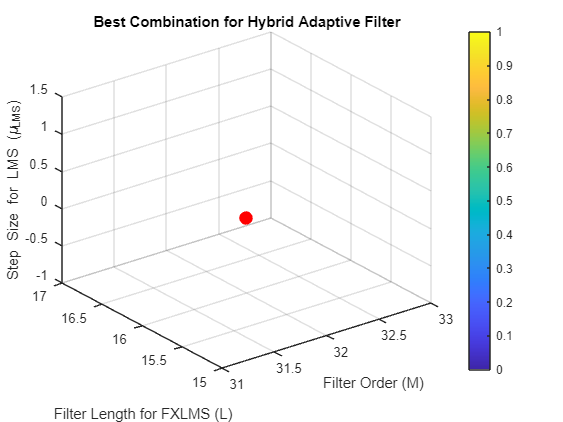


% Plot the best combination
best_SNR_plot = SNR_improvements(best_M_idx, best_L_idx, best_mu_lms_idx, best_mu_fxlms_idx);

figure;
scatter3(best_M, best_L, best_mu_lms, 100, best_SNR_plot, 'r', 'filled');
xlabel('Filter Order (M)');
ylabel('Filter Length for FXLMS (L)');
zlabel('Step Size for LMS (\mu_{LMS})');
colorbar;
title('Best Combination for Hybrid Adaptive Filter');